# Testar MEuler

26/04/2021     Paulo Gouveia        a2020121705.isec.pt

26/04/2021     Miguel Ferreira       a2020107016.isec.pt

26/04/2021     Pablo Amaral         a2020143935.isec.pt

## Exercício que consta no anexo de manuscritos da AM2_Matemática 

Aula04T1_Pós-laboral,

26/03/2021     Arménio Correia     armenioc@isec.pt

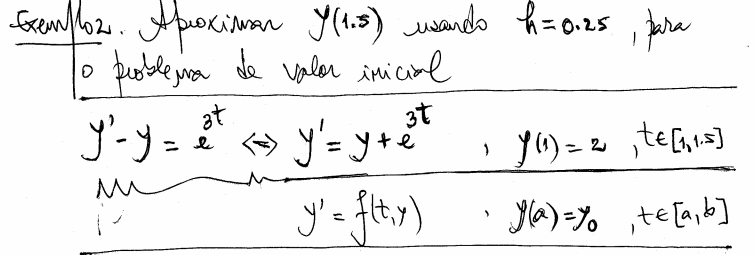

clear
%help function_handle

syms y(t)

f =@(t,y) y+exp(3*t)

f = function_handle with value:
    @(t,y)y+exp(3*t)


%f(0,1)
a = 1

a = 1

b = 1.5

b = 1.5000

n = 20

n = 20

y0 = 2

y0 = 2



yODE45 = NODE45(f,a,b,n,y0)

yODE45 =     2.0000    2.5786    3.2129    3.9076    4.6677    5.4985    6.4058    7.3960    8.4757    9.6522   10.9334   12.3278   13.8446   15.4936   17.2855   19.2317   21.3448   23.6379   26.1257   28.8235   31.7483



sExata = dsolve(diff(y,t)==f(t,y),y(a)==y0)

$$sExata = \frac{{\mathrm{e}}^{3\,t}}{2}+{\mathrm{e}}^{t}\,\left(2\,{\mathrm{e}}^{-1}-\frac{{\mathrm{e}}^{2}}{2}\right)$$

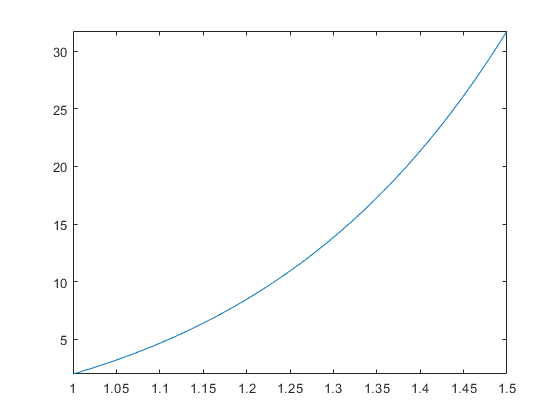

fplot(sExata,[a,b])


g =@(t) eval(vectorize(char(sExata)))

g = function_handle with value:
    @(t)eval(vectorize(char(sExata)))



h = (b-a)/n;
t = a:h:b;
yExata = g(t);
erroODE45 = abs(yExata-yODE45);
tabela = [t.',yExata.',yODE45.',erroODE45.']

tabela =     1.0000    2.0000    2.0000    0.0000
    1.0250    2.5786    2.5786    0.0000
    1.0500    3.2129    3.2129    0.0000
    1.0750    3.9076    3.9076    0.0000
    1.1000    4.6677    4.6677    0.0000
    1.1250    5.4985    5.4985    0.0000
    1.1500    6.4058    6.4058    0.0000
    1.1750    7.3960    7.3960    0.0000
    1.2000    8.4757    8.4757    0.0000
    1.2250    9.6522    9.6522    0.0000


array2table(tabela,"VariableNames",{'t','Exata','ODE45','erroODE45'})

ans = 21×4 table
      t      Exata     ODE45     erroODE45 
    _____    ______    ______    __________

        1         2         2    1.7764e-15
    1.025    2.5786    2.5786    4.0596e-08
     1.05    3.2129    3.2129    3.4539e-08
    1.075    3.9076    3.9076    4.7646e-08
      1.1    4.6677    4.6677    3.9576e-08
    1.125    5.4985    5.4985    5.5867e-08
     1.15    6.4058    6.4058    4.5395e-08
    1.175     7.396     7.396    6.5448e-08
      1.2    8.4757    8.4757    5.2122e-08
    1.225    9.6522    9.6522    7.6611e-08
     1.25    10.933    10.933    5.9902e-08
    1.275    12.328    12.328    8.9615e-08
      1.3    13.845    13.845    6.8902e-08
    1.325    15.494    15.494    1.0476e-07
     1.35    17.285    17.285    7.9319e-08
    1.375    19.232    19.232    1.2239e-07


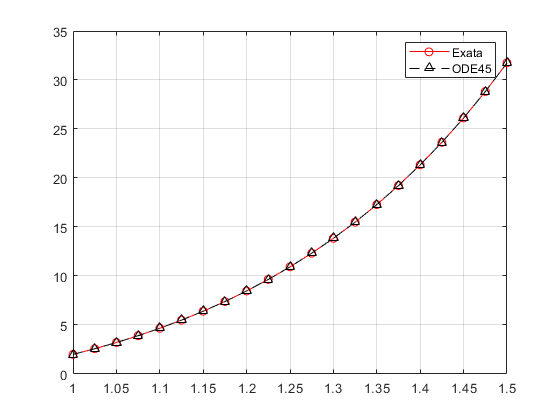


plot(t,yExata,"-ro")
hold on
plot(t,yODE45,"k^--")
hold off
grid on
legend('Exata','ODE45')


%whos

 
